# Bode Plots with a Raspberry pi Pico

© B. Rasnow 4 Feb 25

## Introduction

We have an automated function generator and LM317 DC power supply voltage (although with measurable PWM noise). We previously calibrated `pvolts2pwm` and `pfreq2pwm` functions that control the LM317 DC power supply and XR2206 function generator respectively. We also spent an hour realizing that long unshielded wires and especially, long breadboard busses, add noise to function generator signals. And our `trim` function is very sensitive to noise right around its threshold -- that manifests itself in extra threshold crossings and erroneous (higher) measured frequency. 

We could attempt to filter the glitchy (high frequency) noise. Matlab has a very powerful routine called `filtfilt`, that implements an averaging filter with zero phase shift. Designing coefficients for it requires some learning, so here's a useful default smoothing filter that replaces each value in the input vector x with a weighted average of 1/4 of the value above and below it and .5 of its value: `y = filtfilt([.25 .5 .25], 1, x); `

`....`

Let's measure and make a Bode plot of an RC circuit (Fig. 1).

### 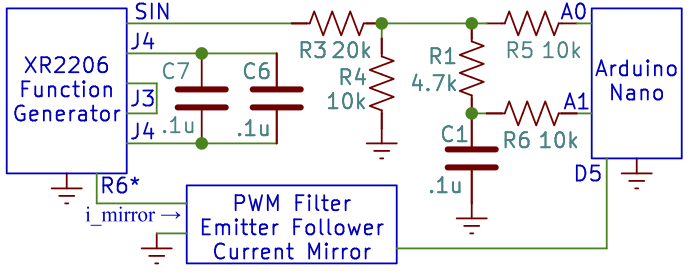

Figure 1. Circuit for measuring Bode plot of R1-C1 with the Arduino.

Considering what each component did will guide us into what should change. 

- J3, C6 and C7 -- 0.2uf moved the automated frequency range of the function generator lower to avoid aliasing -- which the Nano did above  $f_{Nyquist} \approx$ 2.2kHz `= dat.sr / 2`. The Pico aliases around $f_{Nyquist} \approx$ 57kHz, but we added a $5\mu sec$ delay between each sample that lowered that by ~1/2. Measuring 1000 samples instead of 400 lets us measure proportionately lower frequencies too -- more samples to fit a full period into. The automated frequency range we found last time was ~169Hz-8100Hz. So we don't need C6 nor C7, just jumper J3 and `writeline(pico,'d 5')` to establish the delay. 

- Voltage dividers R3 and R4 need to be changed -- we need to divide the max(Vout) ~ 12V by around 4 instead of 3, to guarantee the Pico sees <3.3V. We already selected voltage divider resistors that do this, from earlier: 

- R1 and C1 were chosen to have a corner or "cutoff" frequency ([https://en.wikipedia.org/wiki/Cutoff_frequency](https://en.wikipedia.org/wiki/Cutoff_frequency)) near the center of the (logarithmic) Bode plot. What frequency is half way between 169Hz and 8100Hz on a log scale? The answer is $f_{corner} \approx \sqrt{f_{min} * f_{max}}$, also known as the geometrical mean ([https://en.wikipedia.org/wiki/Geometric_mean](https://en.wikipedia.org/wiki/Geometric_mean)). 

- R5 and R6 protect the microcontroller from accidental overvoltage, but they are too large a voltage divider for the lower internal impedance of the Pico and should be replaced with 1k resistors. R6 is really unnecessary because R1 protects A1.

pscope; % initialize pico and graphics
writeline(pico,'d 5')
writeline(pico,'p 1023'); % pause(75)-- it takes forever to stabilize at the top
R4 = 1969; % 2k
R3 = 5063; % 5.1k
fcorner = sqrt(169*8200) % middle of our frequency range

fcorner = 1.1772e+03

Recall we previously wrote a function to compute the corner frequency of an RC series circuit: 

help fc

  function fcorner = fc(R,C)
  return the corner = cutoff frequency (Hz) for an RC circuit
  with R(ohms) and C(farads)
  time constant tau = RC, corner frequency = 1/tau = 1/(2*pi*R*C)



fc(4.7e3,.1e-6) % prior corner frequency

ans = 338.6275

To make it ~3 times higher, make R or C 3 times smaller. Two 100nf in series makes 50nf, and 4.7k --> 2k might do it. A little trial and error suggested another resistor pair is closer (and offers a higher impedance -- less loading of the function generator output at high frequencies) 

fcorner = fc(3000,48e-9)

fcorner = 1.1052e+03

using a 2k + 1k in series with 2 100nf in series puts the predicted corner frequency very close to the geometric mean frequency.

**Make sure to activate deskewing before doing the Bode plot **-- I could try to alert you with a bigger, bolder font, but isn't it better to just automate the selection: 

dat.skew.Value = 3; % set Fourier deskewing

Do verify that the GUI changed to reflect this choice. 

Because of settling time, we want to start at the top frequency and move downward, and if we want logarithmically spaced frequencies, we should generate them from low to high and flip the vector:

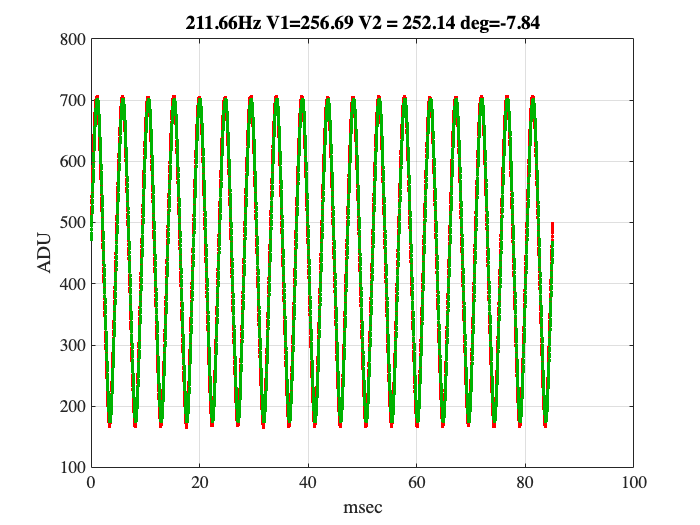

figure; 
targetFreqs = flipud(logspace(log10(169),log10(8100),50)');
writeline(pico,'p 1023'); % pause(75) % 
fmeas = zeros(size(targetFreqs));
amplitudes = zeros(length(targetFreqs),2);
tic; 
for i=1:length(targetFreqs) 
    pfreq2pwm(targetFreqs(i), pico);
    pause(.2);
    dat.runOnce = true;
    pscope; % --> new data 
    fmeas(i) = dat.freq;
    amplitudes(i,:) = dat.ampl;
   %  fprintf('.');
end 

toc

Elapsed time is 21.885193 seconds.


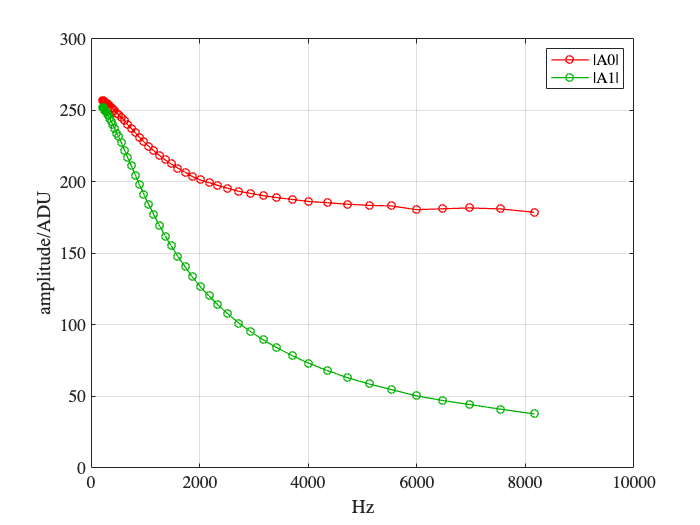

writeline(pico,'p 1023'); % let it rest at highest f
figure; % take a quick peek at raw data
plot(fmeas,abs(amplitudes),'-o'); grid;
xlabel('Hz'); ylabel('amplitude/ADU')
legend('|A0|','|A1|')

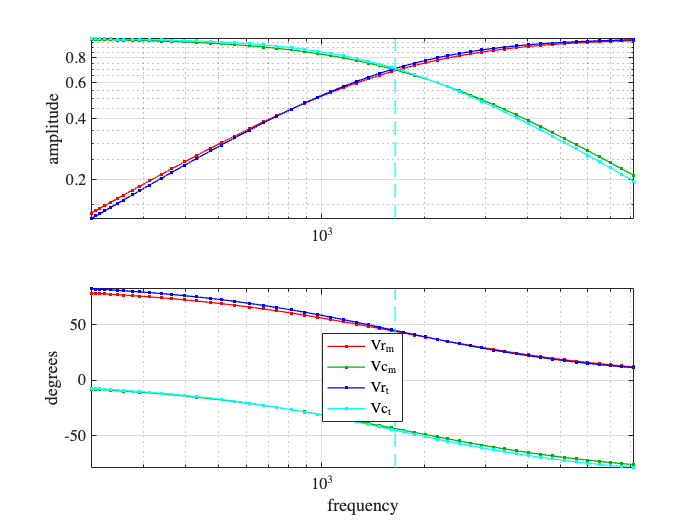

C1 = .65*50e-9; % 2 100nf in series
R1 = 2.99e3; % 1000+2000 ohms in series
vr = amplitudes(:,1)-amplitudes(:,2); % voltage across R1
vc = amplitudes(:,2); % voltage across C1
vr = vr ./amplitudes(:,1); % divide by Vo normalizes vr to a gain
vc = vc ./amplitudes(:,1); % divide by Vo normalizes vc to a gain
% compare to theory
fcorner = fc(R1,C1);
zc1 = zc(C1, fmeas);
vth = [R1 ./ (R1+zc1), zc1 ./ (R1+zc1)]; % voltage divider equation

bodePlot(fmeas,[vr vc vth],fcorner)
legend('Vr_m','Vc_m','Vr_t','Vc_t','location','best')

The data looks smooth, but not as good as with the Arduino. Perhaps because the Pico is adding C on the order of 10-100pF in parallel? Or its adding R ~ 1M in parallel with C? The C's are atrociously off in value, using some monolithic 100nfs, 2 in series yielded a better fit. Too bad our kit's DMM won't measure these capacitors at all. 

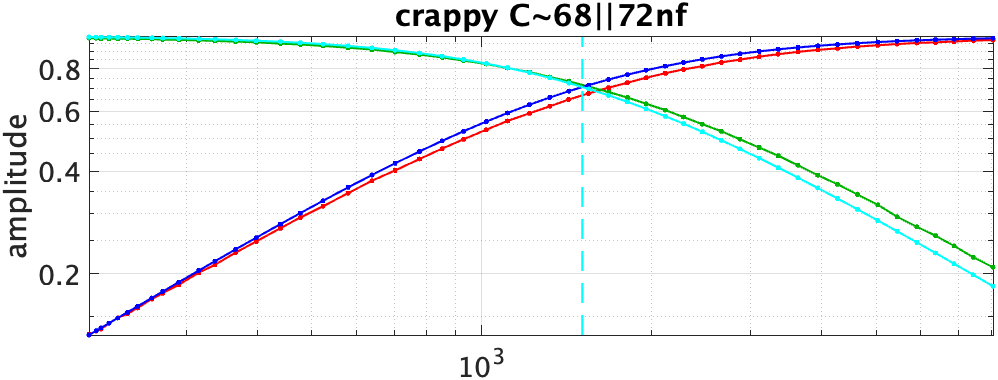

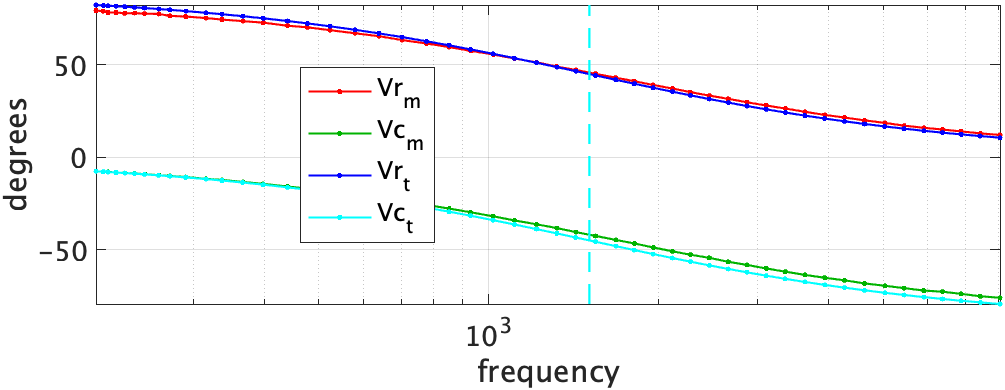

A key point that 100pF capacitors can be problematic in large, breadboarded circuits like this, because parasitic pF's are everywhere. If you have C = 1uF = 1000pF, then a few pF here and there don't make a big error. But starting with 100pF, a stray 10pF will cause a 10% error. Likewise if the circuit has a series resistance <50k$\Omega$ then a 1M load impedance doesn't make much difference:

zp(50e3,1e6), (ans-50e3)/50e3

less than 5% to be precise. But a 1M circuit loaded with a 1M measuring system has a 50% error. What we see above at low frequencies is consistent with loading. So "low impedance" or "high impedance" is always relative to what it's connected to. 

What is the input impedance of a Pico? Goggle led to this discussion: [https://forums.raspberrypi.com/viewtopic.php?t=299757.](https://forums.raspberrypi.com/viewtopic.php?t=299757.) This doesn't seem pico specific, but for any Raspberry pi's GPIO pin, and some of the participants don't appear to be professional engineers, in the sense that they tried to measure Zin directly with an Aneng ohmmeter (we know what that is ;-). The GPIO pin is dynamic, so it's $Z_{Thevenin}$ likely is different during the moments that its measuring a voltage. Let's do a little modeling to see if we can understand this better. 

Perhaps the most productive way to explore the Bode plot errors quantitatively is to tweak R1 and C1 values and rerun the section. I found the following values gave a much better fit, tweaking R1 and C1 by 10% and adding 15M$\Omega$ in parallel with C1, which would be called a "leakage" -- leaking the charge off of C1. Significant phase errors on Vc at high frequency, where simulated Vr is a little high can be peeled off with some more trial and error. But the goal isn't to "perfectly" fit measurements and theory, but rather to verify the measurements are plausible and we've done that. 

R1 =  1.1e6; C1 = 110e-12;
zc1 = zc(C1, fmeas);
zc1 = zp(15e6,zc1);
vth = [R1 ./ (R1+zc1), zc1 ./ (R1+zc1)]; % voltage divider equation
bodePlot(fmeas,[vr vc vth],fcorner)
legend('Vr_m','Vc_m','Vr_t','Vc_t','location','best')

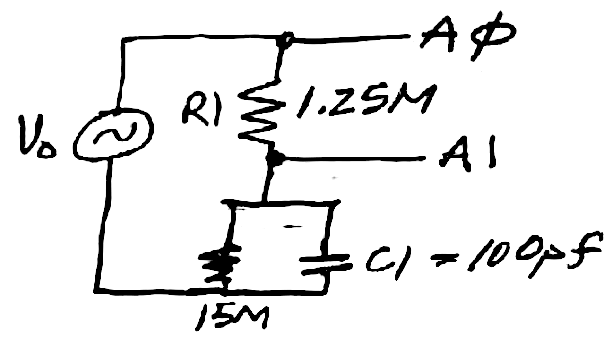

=====end 

A simple model of the Pico's input impedance is an R||C and we'll make wild initial guesses of their values -- e.g., 10M || 10pF -- and iteratively tweak them. 

zc1 = zc(C, fmeas);
zc_pico = zc(10e-12, fmeas);
zpico = zp(10e6,zc_pico);
zcp = zp(zc1, zc_pico);
vr_t = R ./(R + zcp);
vc_t = zcp ./(R+zcp);
bodePlot(fmeas, [vr vc vr_t vc_t], fcorner);
legend('Vr_m','Vc_m','Vr_t','Vc_t','location','west')

That shifted the corner in the right direction, but not convincing ... let's try Zpico = Rp + Cp, i.e., resistor and cap in series. 

R = 1e6; C = 100e-12;
zc1 = zc(C, fmeas);
Rp = 10e6;
zc_pico = zc(10e-12, fmeas); 
z2 = zp(zc1, (Rp+zc_pico));
vr_t = zc_pico ./ (Rp + zc_pico);
vc_t = z2 ./ (R+z2) .* zc_pico ./ (Rp + zc_pico);
bodePlot(fmeas, [vr vc vr_t vc_t], fcorner);
legend('Vr_m','Vc_m','Vr_t','Vc_t','location','west')

[https://www.physics.utoronto.ca/~phy224_324/experiments/thermal-noise/Thermal-Noise.pdf](https://www.physics.utoronto.ca/~phy224_324/experiments/thermal-noise/Thermal-Noise.pdf) 

 t = table(fmeas, vr*1000, vc*1000) % print table of data

## Reflections

### Reducing PWM noise

With PWM voltage control we saw measurable PWM noise. . 

- First quantify the noise so you'll be able to quantify its reduction. `writeline(pico,'p 512')` should give worst case noise with PWM voltage control and the LM317 output sampled through the voltage divider.  `aspectrum(dat.raw, dat.sr)` should give spectrum and you can either visually or otherwise quantify the 1kHz peak. 

- One solution could be to reprogram the Pico's PWM frequency to e.g., 2kHz. The PWM filter's corner frequency doesn't change, so attenuation should be much more. The question is does this have any unintended consequences? I.e., why not make it 10kHz or 100kHz? Eventually there won't be much room to modulate the pulse width if the pulse repetition rate is too high. 

- Another solution is to add a 3rd stage PWM filter, easiest is in front of the existing two, but it has to be low impedance yet not too much of a load on the Pico's GPIO pin. 

- Add an electrolytic capacitor between the voltage divider and ground -- since we're measuring DC, this will become a low pass filter. I found that reduced 1kHz PWM noise from ~2ADU to 0.1ADU. 

- Do nothing for now. We can always revisit this. 